load parkingTrainGTManual.mat
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [400×3 table]


[imds, blds] = objectDetectorTrainingData(gTruth);

countEachLa0bel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     167        144    
    Charger        106        106    
    EV             223        201    


bboxes = createBoundingBoxTable(blds)

bboxes = 496×3 table
    ImgIdx               BBox                  Label   
    ______    ___________________________    __________

       1      177      85     127     146    EV        
       2      201     108      77     145    Accessible
       3      186      92     111     191    Accessible
       4      210     112      59     134    Accessible
       5      171      97     138     145    EV        
       6        3      65     185     195    EV        
       7       87      53     210     208    EV        
       8       98    35.5     300     285    EV        
       9      134    69.5     225     251    EV        
      10      201     106      77     144    Accessible
      11      127      60     238     260    EV        
      12      152    52.5     176     268    EV        
      13      199     103      82     115    EV        
      13       10     140      55   

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 496×5 table
    ImgIdx               BBox                  Label       Area     AspectRatio
    ______    ___________________________    __________    _____    ___________

       1      177      85     127     146    EV            18542      0.86986  
       2      201     108      77     145    Accessible    11165      0.53103  
       3      186      92     111     191    Accessible    21201      0.58115  
       4      210     112      59     134    Accessible     7906       0.4403  
       5      171      97     138     145    EV            20010      0.95172  
       6        3      65     185     195    EV            36075      0.94872  
       7       87      53     210     208    EV            43680       1.0096  
       8       98    35.5     300     285    EV            85500       1.0526  
       9

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

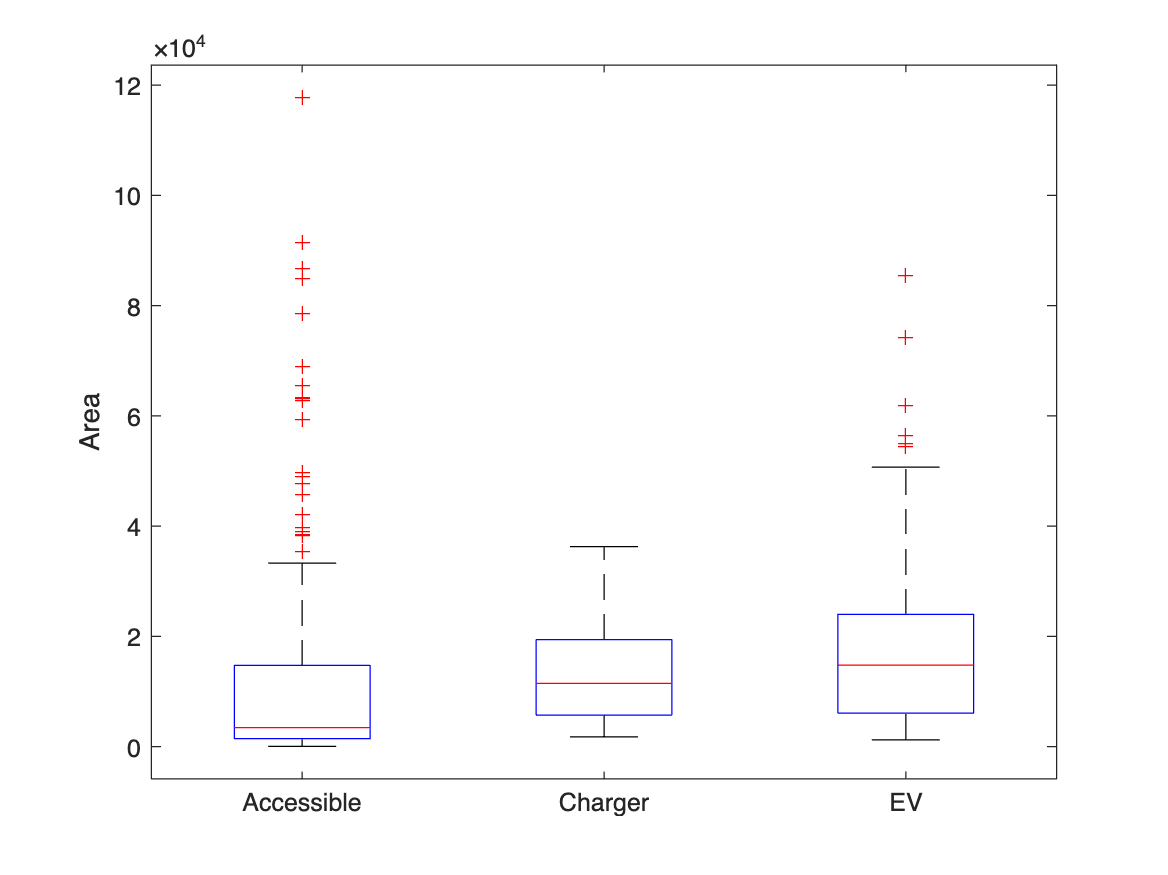

boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

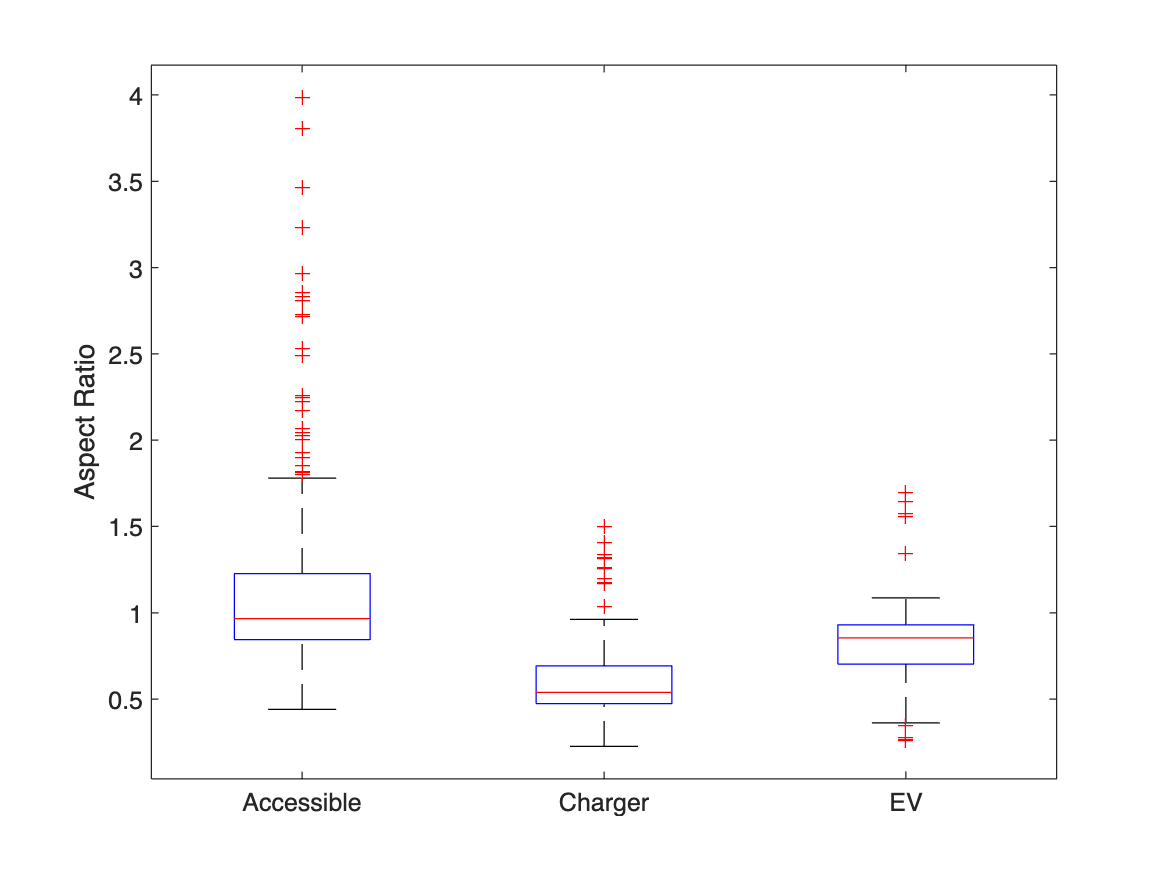

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end

[img, info] = readimage(imds, 1);
size(img)

ans =    320   480     3


nFiles = length(imds.Files)

nFiles = 400

classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


data = combine(imds,blds);

data = shuffle(data);
trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);

trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

opts = trainingOptions("adam","MiniBatchSize", 16, "MaxEpochs",10, "ValidationData",validationData,"ValidationFrequency", 10, "Shuffle","every-epoch", "Plots","training-progress");

detector = yoloxObjectDetector("tiny-coco", classes,"InputSize",[320 480 3]);

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingYoloXLoss    ValidationYoloXLoss
    _____    _________    ___________    _________    _________________    ___________________
      1          1         00:00:06        0.001           12.294                14.586       
      1         10         00:00:46        0.001           8.0563                8.0121       
      1         20         00:01:21        0.001           5.7161                5.8253       
      2         30         00:01:54        0.001           4.5999                5.4433       
      2         40         00:02:28        0.001           4.5489                5.0451       
      3         50         00:03:01        0.001           4.3916                4.8242

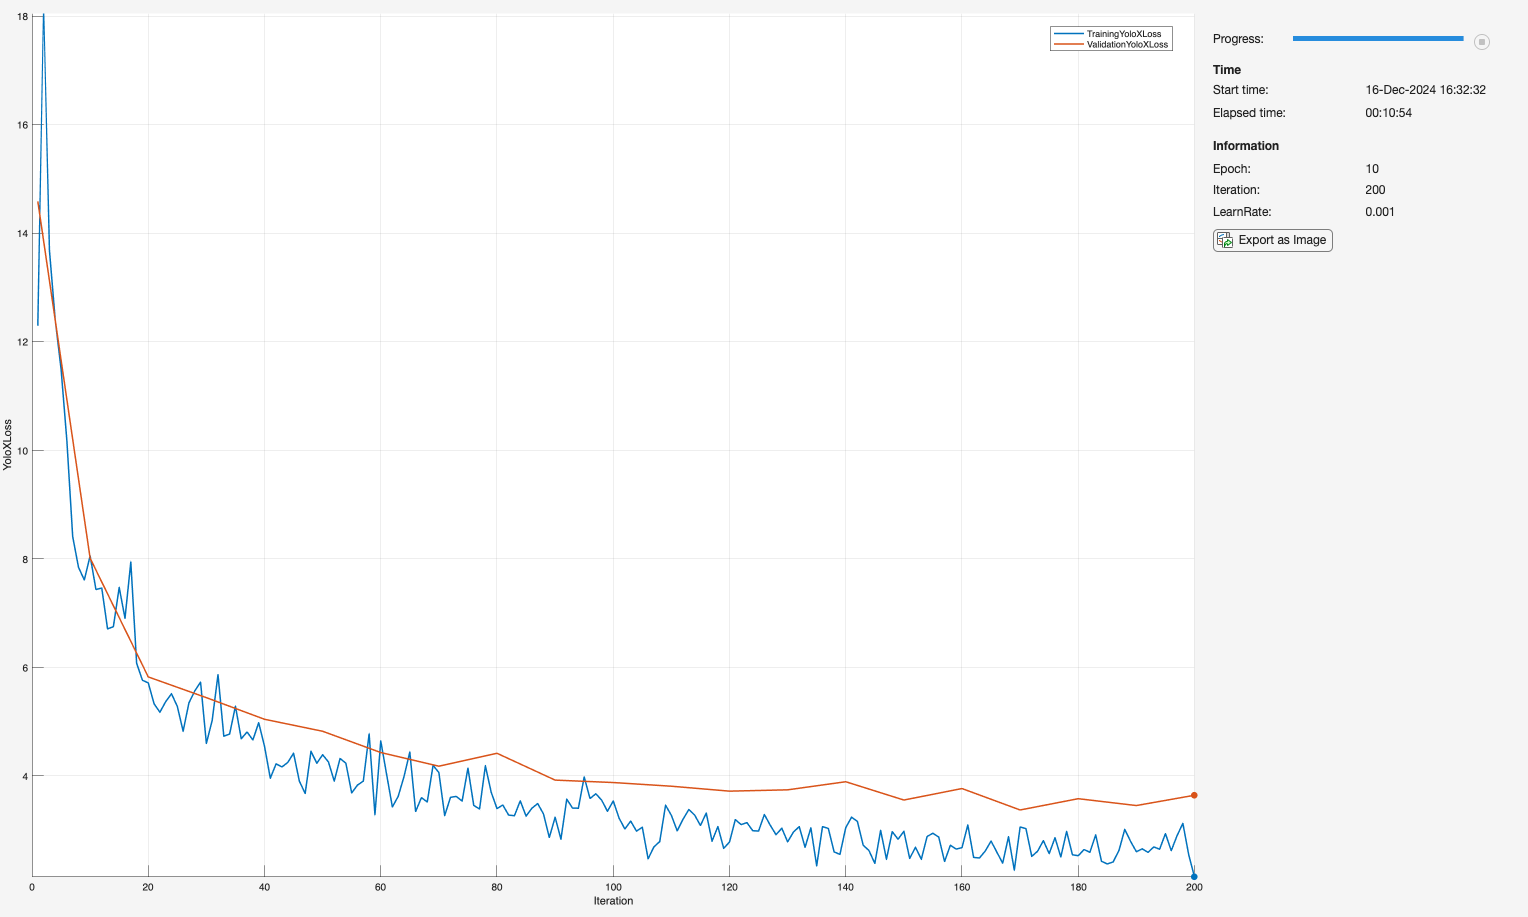

     10         200        00:10:47        0.001           2.1393                3.6452       


[detector, info] = trainYOLOXObjectDetector(trainingData, detector, opts);

load parkingTestGT.mat parkingTestGT;

parkingTestGT

parkingTestGT =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [100×3 table]


[imdsTest, bldsTest] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imdsTest, bldsTest);

testResults = detect(detector, testData, "Threshold", 0.05);

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.5);
ap

ap =     0.6843
    0.8939
    0.9969


[~, idx] = min(ap);
classes(idx)

ans = 1×1 cell array
    {'Accessible'}


mean(ap)

ans = 0.8584

% Vector of detection threshold values to test
thresholds = [0.15, 0.3, 0.55, 0.8];

classes = detector.ClassNames;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

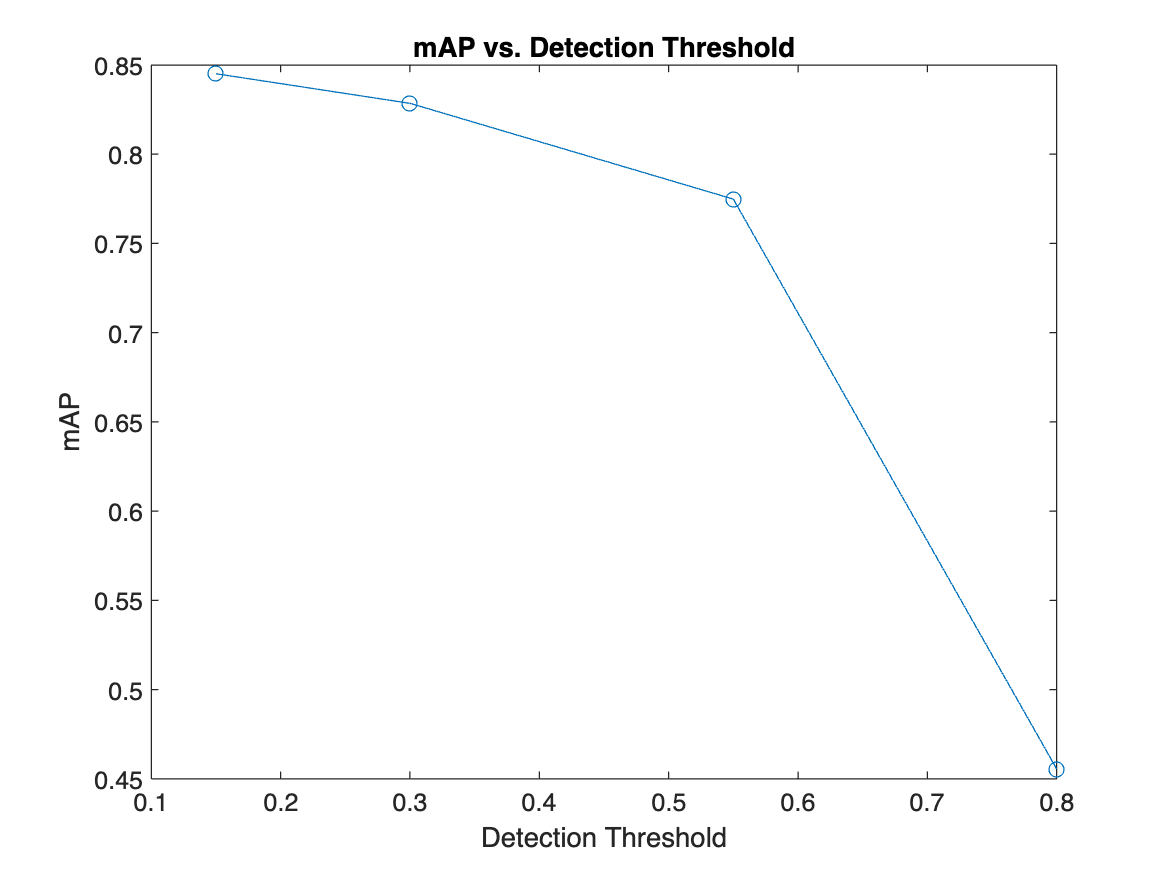

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

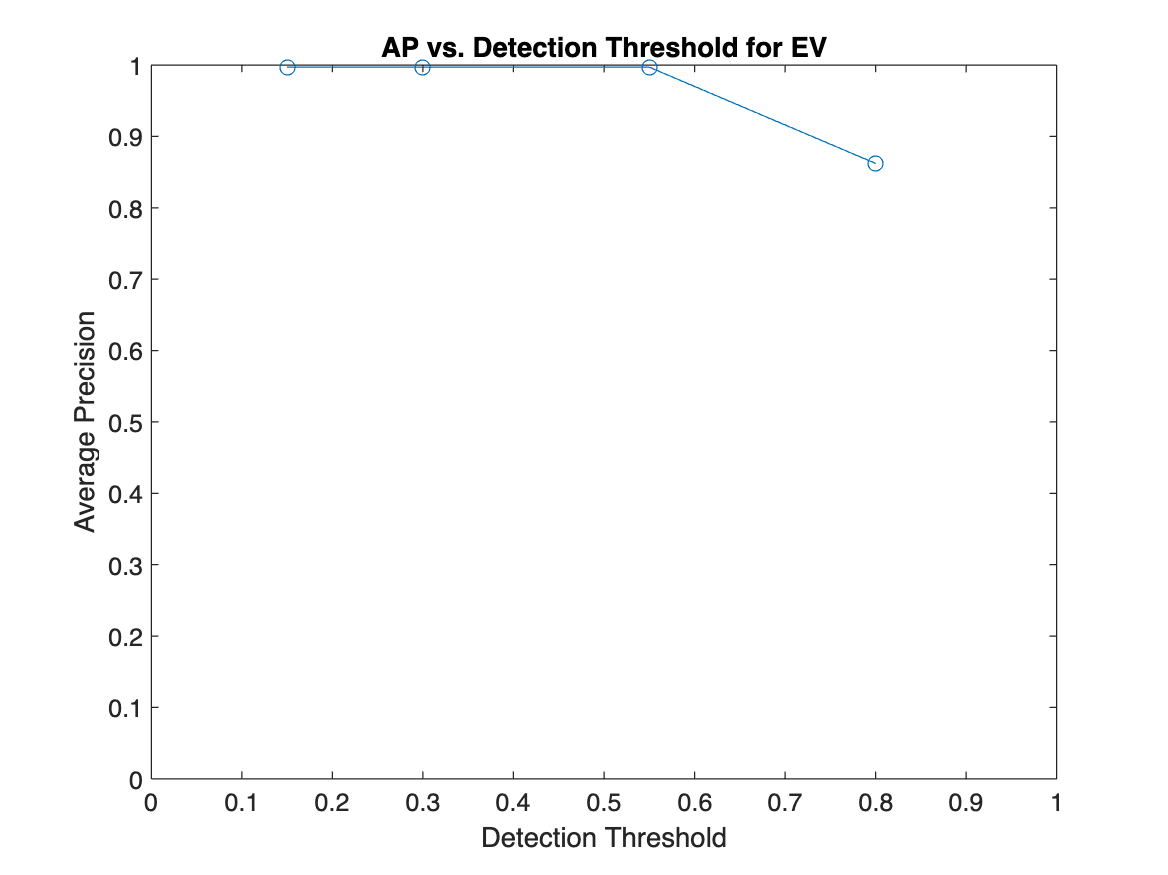

class = 3;
plot(thresholds, apMatrix(class, :), "-o")
title("AP vs. Detection Threshold for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Average Precision")
xlabel("Detection Threshold")